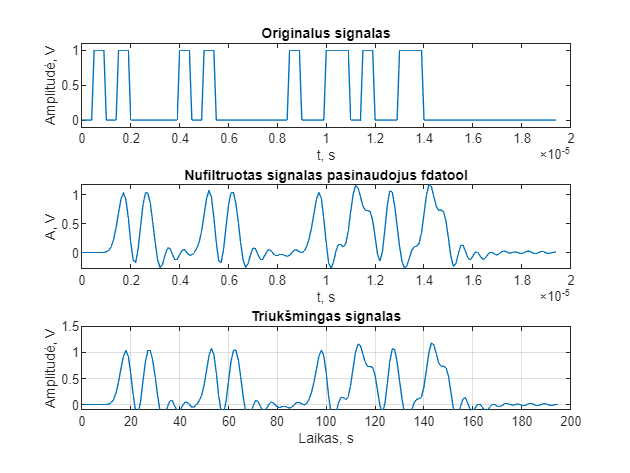

fdiskret = 10E6;
tdiskret = 1/fdiskret;
A = 1;

one = [ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret))];
zero = [zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret))];


preambule = [ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret))];
originalus = [zeros(1, 5), preambule, zeros(1, round(3E-6/tdiskret)), one, zero, one, one, zero, one, zeros(1, 50)];
%N = 4 * 1 / fsignal * fdiskret;
%n = 0:N-1;
%t = 0:1/fdiskret:1/fdiskret*(N-1);
%s = 2+ A * sin(2 * pi * fsignal * n / fdiskret);
N = length(originalus);
n = 0:N-1;
t = 0:1/fdiskret:1/fdiskret*(N-1);

subplot(3, 1, 1)
plot(t, originalus)
xlabel('t, s')
ylabel('Amplitudė, V')
title('Originalus signalas')
ylim([-0.1, 1.1])

%Filtro š
load 'FiltroKoef.mat'
nufiltruotas = filter(Hd, originalus);
subplot(3, 1, 2)
plot(t, nufiltruotas)
title("Nufiltruotas signalas pasinaudojus fdatool")
xlabel("t, s")
ylabel("A, V")


%Triuksmo generavimas
vid = 0;
std = 0.0;
triuksmas = vid + std*abs(randn(1, N));
triuksmasFiltruotas = filter(Hd, triuksmas);
triuksmingasSignalas = nufiltruotas + triuksmasFiltruotas;
subplot(3, 1, 3)
plot(triuksmingasSignalas)
ylabel('Amplitudė, V')
xlabel('Laikas, s')
title('Triukšmingas signalas')
ylim([-0.1, 1.5])
grid on

triuksmingasItamposVertemis = round(triuksmingasSignalas / 1.5*255); %1.5V Vref
for i = 1: length(triuksmingasItamposVertemis)
    if(triuksmingasItamposVertemis(i) > 255)
        triuksmingasItamposVertemis(i) = 255;
    elseif(triuksmingasItamposVertemis(i) < 0)
        triuksmingasItamposVertemis(i) = 0;
    end
end
preambuleItamposVertemis = preambule / 1.5*255;


%Irasyti failaa
%{
testVoltage = fopen('testVoltage.txt','w');
preambuleVoltage = fopen('idealPreambuleVoltage.txt','w');
idealOne = fopen('idealOneVoltage.txt','w');
idealZero = fopen('idealZeroVoltage.txt','w');
for i = 1:length(triuksmingasItamposVertemis)
    temp = dec2bin(triuksmingasItamposVertemis(i), 8);
    fprintf(testVoltage,'%s\n',temp);
end
for i = 1:length(preambuleItamposVertemis)
    temp = dec2bin(preambuleItamposVertemis(i), 8);
    fprintf(preambuleVoltage,'%s\n',temp);
end
for i = 1:length(one)
    temp = dec2bin(one(i), 8);
    fprintf(idealOne,'%s\n',temp);
    temp = dec2bin(zero(i), 8);
    fprintf(idealZero,'%s\n',temp);
end
fclose(testVoltage);
fclose(preambuleVoltage);
fclose(idealOne);
fclose(idealZero);
%}
funkcijuFailas = fopen('Conv_func_data.mif','w');
duomenisIrasyti = [preambuleItamposVertemis, one, zero, zero, one, zero, zero, one, one]; %Praembule, one, zero

fprintf(funkcijuFailas, "WIDTH=8;\nDEPTH=%i;\nADDRESS_RADIX=UNS;\nDATA_RADIX=UNS;\nCONTENT BEGIN \n", length(duomenisIrasyti));

for i = 1:length(duomenisIrasyti)
    %temp = dec2bin(duomenisIrasyti(i), 8);
    %fprintf(funkcijuFailas,'%s\n',temp);
    fprintf(funkcijuFailas,'%i : %i;\n',i-1, duomenisIrasyti(i));
end
fprintf(funkcijuFailas, "END;");
fclose(funkcijuFailas);

testVoltage = fopen('testVoltage.txt','w');
for i = 1: length(triuksmingasItamposVertemis)
    if(triuksmingasItamposVertemis(i) > 255)
        temp = dec2bin(255, 8);
    elseif(triuksmingasItamposVertemis(i) < 0)
        temp = dec2bin(0, 8);
    else
        temp = dec2bin(triuksmingasItamposVertemis(i), 8);
    end
    
    fprintf(testVoltage,'%s\n',temp);
end


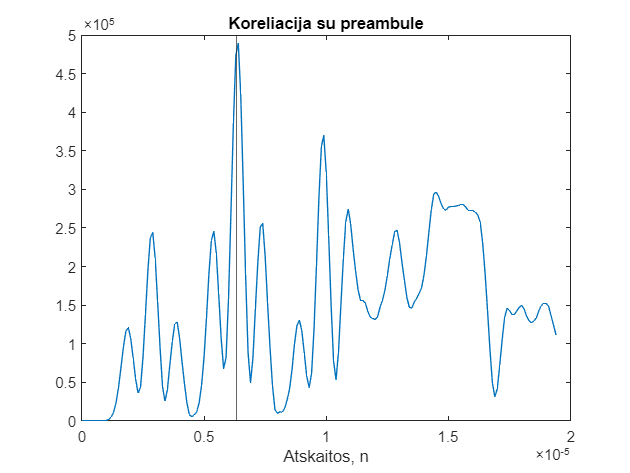


konvoliucija = conv(triuksmingasItamposVertemis, preambuleItamposVertemis);
figure
plot(t, konvoliucija(1:length(triuksmingasItamposVertemis)))
xline(6.34E-6);
title('Koreliacija su preambule')
xlabel('Atskaitos, n')

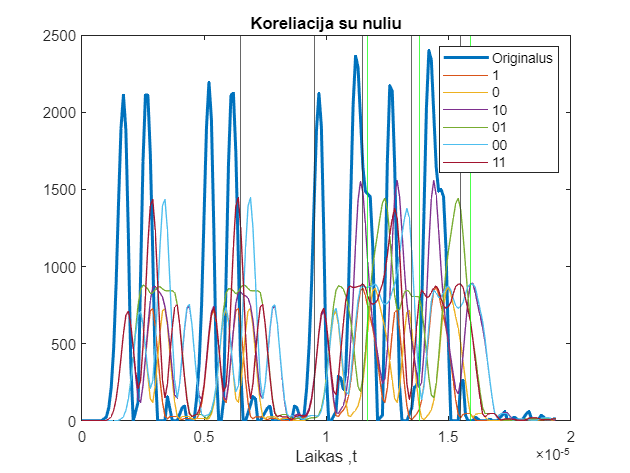


plot(t, triuksmingasItamposVertemis*12, 'LineWidth',2)
hold on
konvoliucija1 = conv(triuksmingasItamposVertemis, one);
plot(t, konvoliucija1(1:length(triuksmingasItamposVertemis)))
title('Koreliacija su vienetu')
xlabel('Atskaitos, n')

konvoliucija2 = conv(triuksmingasItamposVertemis, zero);
plot(t, konvoliucija2(1:length(triuksmingasItamposVertemis)))
title('Koreliacija su nuliu')
xlabel('Laikas ,t')
konvoliucija3 = conv(triuksmingasItamposVertemis, [one, zero]);
plot(t, konvoliucija3(1:length(triuksmingasItamposVertemis)))

konvoliucija4 = conv(triuksmingasItamposVertemis, [zero, one]);
plot(t, konvoliucija4(1:length(triuksmingasItamposVertemis)))

konvoliucija5 = conv(triuksmingasItamposVertemis, [zero, zero]);
plot(t, konvoliucija5(1:length(triuksmingasItamposVertemis)))

konvoliucija6 = conv(triuksmingasItamposVertemis, [one, one]);
plot(t, konvoliucija6(1:length(triuksmingasItamposVertemis)))

xline(6.5E-6);
xline(6.5E-6+3E-6);
xline(6.5E-6+3E-6+2E-6);
xline(6.5E-6+3E-6+4E-6);
xline(6.5E-6+3E-6+6E-6);

xline(117/fdiskret, 'color','green');
xline(138/fdiskret, 'color','green');
xline(159/fdiskret, 'color','green');

legend("Originalus", "1", "0", "10", "01", "00", "11")

hold off

[amplitude, vieta] = max(konvoliucija) %67 atskaitom uzvelina

amplitude = 489940

vieta = 65

vietaLaike = vieta / fdiskret %1.34us uzvelina

vietaLaike = 6.5000e-06